# FACET-II Accelerator Science Example # 1: BPM Orbit Fitting

This example involves taking BPM data (either live or from the archiver, and additionally live buffered data) and performing orbit fitting using the Live Lucretia Model.

**NB: This example neeeds access to EPICS IOC's through the FACET controls system and assumes matlab v.2020a+, started in the matlabTNG/ directory.**

**This example requires a live beam present through to the dump for the tasks to operate as intended and completely make sense.**

We declare the global cell array `BEAMLINE` here for use later, this gets set when instantiating the Live Model.

clear
global BEAMLINE

## Task 1: Load live Lucretia model, instantiate BPM & Corrector objects and checkout acquisition functionality

The following command loads the Lucretia model from the default design location and synchronizes Klystrons, Quads, Sextupoles with control system values and sets energy profile.

LLM = F2_LiveModelApp ;

Apr 13, 2022 8:58:54 AM org.epics.ca.impl.repeater.CARepeaterServiceInstance activate
INFO: The CA Repeater is already running on port 5069.
Apr 13, 2022 8:58:54 AM org.epics.ca.impl.repeater.CARepeaterServiceInstance activate
INFO: Possibly it was started previously by another operating system process.


13-Apr-2022 08:58:55:
Starting LEM Application...
13-Apr-2022 08:58:55:
Loading Lucretia Model...
13-Apr-2022 08:59:00:
Linking to EPICS PVs...
Initial Eref:
    0.0060    0.1251    0.3394    4.5000   10.0000

13-Apr-2022 08:59:00:
Updating with live data...
Initializing labCA Release '86ffed6-dirty'...
Author: Till Straumann <strauman@slac.stanford.edu>
    0.0060    0.1250    0.2735    4.3068   10.1958

    0.0060    0.1251    0.3398    4.5671   10.2593

    0.0060    0.1251    0.3394    4.4993    9.9308

    0.0060    0.1251    0.3394    4.5000   10.0011

    0.0060    0.1251    0.3394    4.5000   10.0000

13-Apr-2022 08:59:15:
Initialization complete.


The returned `LiveModel` object `LLM `is mostly a container for the underlying model objects we care about: principally the `LucretiaModel` object found in `LLM.LM` and the `LEM` object (which contains most of the smarts for syncing the model with the controls) found in `LLM.LEM`. An important method is `UpdateModel` which can be called to refresh the model with external changes in the control system (a future update will provide for the possibility of autoupdating).

We make our own local copy of a `LucretiaModel` object for playing with- the copy command is important as simply re-assigning it (e.g. as `LM=LLM.LM`) will just make a pointer to the original.

LM = copy(LLM.LM) ; % Make our own local copy of the LucretiaModel

By default,  objects will operate on the entire machine. Sometimes it can be helpful to work on a reduced set of objects, for example to speed up data retieval. The machine is subdivided into 11 regions, the definition for which can be found in the `LucretiaModel` class.

disp(LucretiaModel.ModelRegionName)

    "INJ"
    "L0"
    "DL1"
    "L1"
    "BC11"
    "L2"
    "BC14"
    "L3"
    "BC20"
    "FFS"
    "SPECTDUMP"



Here, lets concentrate just on the L3 linac section, plus BC20. Then make BPM and Magnet objects.

LM.UseRegion = [0 0 0 0 0 0 0 1 1 0 0] ; % Select L3+BC20 only
BPMS = F2_bpms(LM) ; % F2_bpms makes its own copy of the LucretiaModel

Setting severity REJECTION level to 4


MAGS = F2_mags(LM) ; % F2_mags makes its own copy of the LucretiaModel

Now, we shall refine the MAGS class to make a Corrector object.

COR = copy(MAGS) ; COR.MagClasses = ["XCOR" "YCOR"] ;

Lets now fetch the current BDES values from the control system for the correctors.

COR.ReadB ;

**NB: the **`readB`** method stores the control system values only locally to the F2_mags object, the in-memory Lucretia model is defined by the global variables (BEAMLINE,PS,KLYSTRON). To both read in the new values AND set them into the in-memory model, use **`readB(true)`**.**

Take a look at the read values by putting it into a Matlab table.

COR_Name = COR.LM.ModelNames ; % Using a LucretiaModel object method attached to the F2_mags object to grab names
COR_BDES = COR.BDES_cntrl; COR_BACT = COR.BACT_cntrl; COR_BMAX = COR.BMAX;
disp(table(COR_Name,COR_BDES,COR_BACT,COR_BMAX)) ;

    COR_Name      COR_BDES       COR_BACT      COR_BMAX
    _________    ___________    ___________    ________

    "XC14900"     -0.0063369     -0.0063253    0.06243 
    "YC14900"      0.0039191      0.0039208    0.06243 
    "XC15202"       0.013988       0.013986    0.06243 
    "YC15203"              0     5.0236e-05    0.06243 
    "XC15302"              0       1.61e-05    0.06243 
    "YC15303"       0.019667        0.01966    0.06243 
    "XC15402"      0.0066694      0.0066629    0.06243 
    "YC15403"              0     -3.348e-06    0.06243 
    "XC15502"              0     1.6888e-05    0.06243 
    "YC15503"      0.0040953      0.0040843    0.06243 
    "XC15602"      0.0060823      0.0060815    0.06243 
    "YC15603"              0    -6.3677e-06    0.06243 
    "XC15702"              0     1.2046e-05    0.06243 
    "YC15703"     -0.00

Now lets turn to the BPMS. First, try getting 10 BPM readings from the EPICS BPM repeater and plotting the orbit.

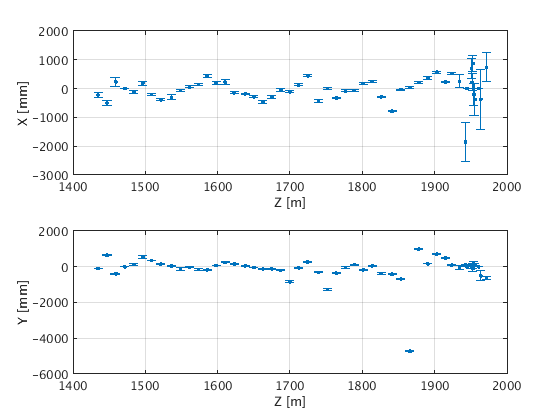

BPMS.readnp(10) ;
BPMS.plot ;

NB: the raw data is stored in BPMS.xdat / ydat / tmit . Lets look at some derived data in a table. BPMS stores values in mm/mrad units.

BPM_Name = BPMS.modelnames ; % There is also "bpmnames" which has the the control system BPM names
Z = BPMS.modelZ ; % Linac z co-ordinate
X_mean = BPMS.xave ; Y_mean = BPMS.yave ;
X_err = BPMS.xrms ; Y_err = BPMS.yrms ;
TMIT_mean = BPMS.tmitave; TMIT_err = BPMS.tmitrms ;
disp(table(BPM_Name,Z,X_mean,X_err,Y_mean,Y_err,TMIT_mean,TMIT_err)) ;

     BPM_Name       Z         X_mean       X_err       Y_mean       Y_err      TMIT_mean      TMIT_err 
    __________    ______    __________    ________    _________    ________    __________    __________

    "BPM15201"    1434.7      -0.22215    0.099062    -0.094508     0.01954    4.6181e+09    6.6393e+07
    "BPM15301"      1447      -0.50136    0.070986      0.64345    0.031123    4.3738e+09    7.7312e+07
    "BPM15401"    1459.4       0.23361     0.15163     -0.38938    0.039022    4.6356e+09    7.3096e+07
    "BPM15501"    1471.7             0           0            0           0             0             0
    "BPM15601"      1484      -0.11808    0.056425      0.12708    0.076373    4.6544e+09    8.5905e+07

xmref=X_mean.*1e-3; ymref=Y_mean.*1e-3; % Store these as reference orbits for later

`readbp` simply reads from the EPICS PVs at the beam rate, it isn't guaranteed that the individual readings are synchronous. To achieve this, we use the `readbuffer` method which reads BPM data from BSA EPICS and/or uses AIDA-PVA SCP BUFFACQ as required (and additionally matches up the pulse ID's as needed).

BPMS.readbuffer(20) ; % The stored data is synchronous
fprintf(BPMS.nread+" Pulses acquired\n") ;

19 Pulses acquired


NB: there is an uncertain delay in launching the command to acquire data through AIDA-PVA. To ensure that the EPICS and SCP data overlap, additional EPICS data is taken. This additional fraction is set by the `nepicsbuffer` property and can be increased if fully overlapping data is not acquired (as reported in the `nread` property).

Finally, lets grab 10 BPM readings from the archiver (these are never going to be pulse-synchronous and should only be used for averaging).

BPMS.readnp(10,[2022 4 10 21 22 0]);

Reading BPMS:LI15:201:X57
Calling singleHistory
Asking history for BPMS:LI15:201:X57 from 2022-04-11T04:22:00.000Z to 2022-04-11T04:23:40.000Z
mshankar Done getting history for BPMS:LI15:201:X57 from 2022-04-11T04:22:00.000Z to 2022-04-11T04:23:40.000Z
Reading BPMS:LI15:301:X57
Calling singleHistory
Asking history for BPMS:LI15:301:X57 from 2022-04-11T04:22:00.000Z to 2022-04-11T04:23:40.000Z
mshankar Done getting history for BPMS:LI15:301:X57 from 2022-04-11T04:22:00.000Z to 2022-04-11T04:23:40.000Z
Reading BPMS:LI15:401:X57
Calling singleHistory
Asking history for BPMS:LI15:401:X57 from 2022-04-11T04:22:00.000Z to 2022-04-11T04:23:40.000Z
mshankar Done getting history for BPMS:LI15:401:X57 from 2022-04-11T04:22:00.000Z to 2022-04-11T04:23:40.000Z
Reading BPMS:LI15:501:X57
Calling singleHistory
Asking history for BPMS:LI15:501:X57 from 2022-04-11T04:22:00.000Z to 2022-04-11T04:23:40.000Z
mshankar Done getting history for BPMS:LI15:501:X57 from 2022-04-11T04:22:00.000Z to 2022-04-11T04

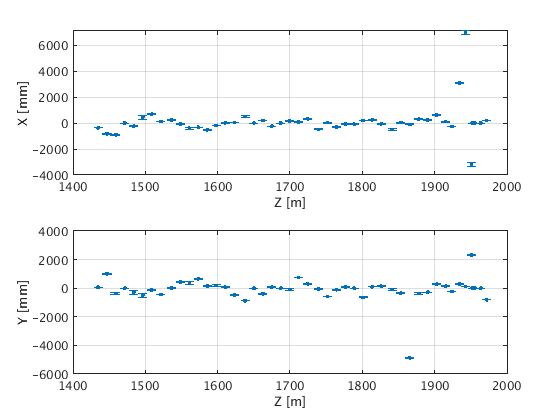

BPMS.plot ;

## Task 2: Static orbit fitting

We will measure an averaged orbit and use the mean and rms BPM readings to fit an orbit [x,x',y,y',dE/E] at a chosen location. To do this, we will take a series of BPM readings and form the mean and rms vectors. Then form the respone matrix between BPMs and the fit location. We then need to solve the linear matrix equation: `Ax = B`, where `A` is the response matrix, `B` the vector of BPM readings and x the orbit at the fit location. This can be doine simply by using the matlab backslash operator as: x = A\b. To make use of the BPM errors (rms spread of readings), we can however use the `lscov` function which instead solves the equation (in the least-squares sense): `(A*x-B)'*inv(V)*(A*x-B) `where V is the weight vector (STD of BPM readings) and we assume the errors are uncorrelated. If the errors are large, `lscov` often returns just a flat orbit- experiment with using backslash and `lscov` with and without errors.

Lets look at the case of fitting an orbit into BC20 and choose BPM 2050 as our fit location (first BPM in the dispersive region of BC20).

fitid = findcells(BEAMLINE,'Name','M1E') ; % LI20:BPMS:2050 BEAMLINE index

Using our already configured `BPM` object, lets grab a fresh set of data and extract the mean and rms BPM orbit vectors. Stored in BPMS object in mm, mrad units, change to m, rad units for fitting calculations.

BPMS.readnp(10) ; % Get 10 beam pulses of BPM readings
xm = BPMS.xave.*1e-3; xerr = BPMS.xrms.*1e-3 ;
ym = BPMS.yave.*1e-3; yerr = BPMS.yrms.*1e-3 ;
xm=xm-xmref; ym=ym-ymref; % Subtract previously stored "reference orbit"

First, we need to get a matrix of linear response matrix elements which maps the first BPM to each BPM in the 5D variables of interest (x,x',y,y',dE/E). To do this we use the Lucretia function `RmatAtoB` which needs the `BEAMLINE` elements of the BPMs in addition to the fit location as arguments. We can make use of the `F2_bpms` object property modelID which has already generated these for our selected model region.

We are going to include the coupling responses also to allow for the presence of skew-quad fields.

bpmid = BPMS.modelID ; % BEAMLINE indices of BPMs
% Now we make the response matrix, A, which maps x and y BPM readings to the 5D position at the first BPM
A = zeros(length(xm)+length(ym),5) ; A(1,:) = [1 0 0 0 0] ; A(length(xm)+1,:) = [0 0 1 0 0] ;
for ibpm=2:length(bpmid)
  [~,R] = RmatAtoB(bpmid(1),bpmid(ibpm)) ; % Returns 6x6 linear response matrix (we throw away the status return here)
  A(ibpm,:) = [R(1,1) R(1,2) R(1,3) R(1,4) R(1,6)]; % mapping of first bpm to x dimension of ith BPM
  A(ibpm+length(xm),:) = [R(3,1) R(3,2) R(3,3) R(3,4) R(3,6)]; % mapping of first bpm to y dimension of ith BPM
end

Now use our `lscov` operator to solve for [x,x',y,y',dE/E] at first BPM.

% X_bpm1 = lscov(A,[xm(:);ym(:)],1./([xerr(:);yerr(:)].^2)) ;
X_bpm1 = A\[xm(:);ym(:)] ;
% X_bpm1 = lscov(A,[xm(:);ym(:)]) ;
disp(X_bpm1)

    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0014



As our fit location is after the first BPM, we can simply use a response matrix to transport the beam trajectory co-ordinates as:

[~,R] = RmatAtoB(bpmid(1),fitid); R=R([1:4 6],[1:4 6]); % just need the 5d response matrix (remove z)
X_fit = R * X_bpm1 ;
disp(X_fit)

   1.0e-03 *

   -0.0875
   -0.0145
    0.0216
   -0.0015
   -0.6779



If the desired fit location is upstream of BPM we can trasport it backwards just as simply (e.g. lets get the fitted orbit co-ordinates at the start of the selected model region, L3BEG):

[~,R]=RmatAtoB(double(LM.istart),bpmid(1)); % NB: istart and iend are BEAMLINE indices at region boundaries selected
R=R([1:4 6],[1:4 6]);
X_L3BEG = R \ X_bpm1 ;
disp(X_L3BEG)

    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0015



Finally, lets get the fitted orbit at every BEAMLINE element up to fit location and superimpose that orbit on to BPM orbit plot.

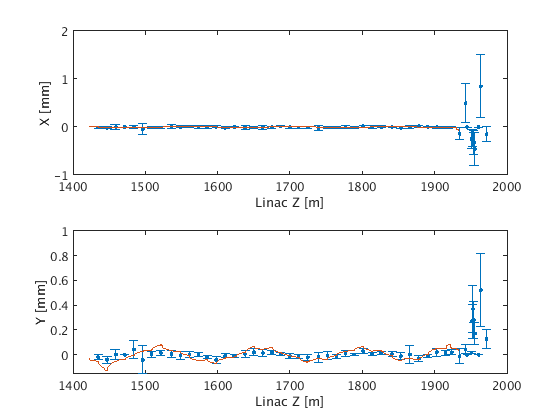

blid = LM.ModelID ; % BEAMLINE elements in selected region
use = blid<=fitid ; blid=blid(use) ; % Select all elements up to and including fit location
X=zeros(5,length(blid)) ; % Cell array to store fitted beam orbit co-ordinates
for n=1:length(blid)
  [~,R]=RmatAtoB(double(LM.istart),blid(n)); R=R([1:4 6],[1:4 6]);
  X(:,n) = R * X_bpm1 ;
end
subplot(2,1,1)
errorbar(BPMS.modelZ,xm.*1e3,xerr.*1e3,'.'); % plot z vs. x BPM readings with errors
hold on
plot(LM.ModelZ(use),X(1,:).*1e3);
hold off
xlabel('Linac Z [m]'); ylabel('X [mm]');
subplot(2,1,2)
errorbar(BPMS.modelZ,ym.*1e3,yerr.*1e3,'.'); % plot z vs. y BPM readings with errors
hold on
plot(LM.ModelZ(use),X(3,:).*1e3);
hold off
xlabel('Linac Z [m]'); ylabel('Y [mm]');

## Task 3: Use buffered BPM acquisition to fit dynamic BPM jitter modes using SVD

Here we used the buffered data acquisition function to get pulse synchronous data and use the Matlab svd routine to examine the orthogonal jitter modes. The mode most correlated to the dispersive BPM (2050) should represent the pulse-pulse energy jitter and we can in principal use this to reconstruct the dispersion function (although in reality there may not be enough naturally occuring energy jitter, it is better to artifically excite this mode by dithering an energy knob).

Grab a bunch of buffered acq pulses, the more the better but we are limited by the SCP depending on the current beam rate. Here, grab 50 as a "safe" number.

**NB: readbuffer steals rate from SCP whilst acquiring data!**

BPMS.readbuffer(50) ; % The stored data is synchronous
fprintf(BPMS.nread+" Pulses acquired\n") ;

50 Pulses acquired


Form raw matices of BPMs vs pulse # and format correctly for passing to the Matlab `svd` algorithm. We will consentrate just on the horizontal plane here.

xd=BPMS.xdat'; xd(isnan(xd))=0; xd=xd-mean(xd); xd=xd.*1e-3;

Now do the svd decomposition. And plot the largest 3 jitter modes.

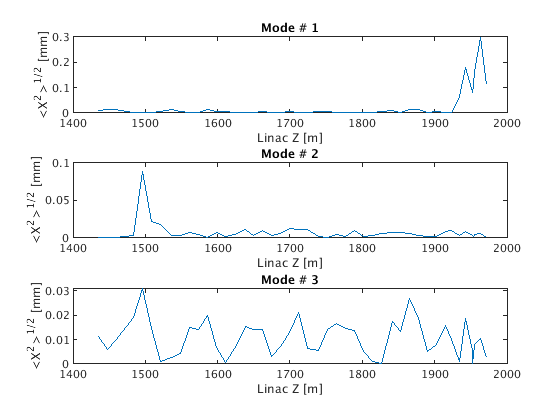

[Ux,Sx,Vtx]=svd(xd); % xd = Ux * Sx * Vtx'
svals=diag(Sx); % mode amplitudes (singular values)
nmodes=3;
x_mode=zeros(nmodes,length(BPMS.xave));
for imode=1:nmodes
  S=zeros(size(Sx)); S(imode,imode)=Sx(imode,imode);
  x_mode(imode,:) = std(Ux * S * Vtx') ;
end
for imode=1:nmodes
  subplot(nmodes,1,imode)
  plot(BPMS.modelZ,x_mode(imode,:).*1e3); title("Mode # "+imode); xlabel('Linac Z [m]'); ylabel('<X^2>^{1/2} [mm]');
end

Which mode looks most like energy? Could calculate correlation coefficients of the various mode patterns vs. dispersion function.

emode=1;

Use design dispersion at energy bpm to get energy

disp = LM.DesignTwiss.etax(fitid) ; % fitid is our 2050 energy BPM from before

Now reconstruct our energy mode and plot dP/P at energy BPM.

S=zeros(size(Sx));S(emode,emode)=Sx(emode,emode);

S =     0.0031         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0    

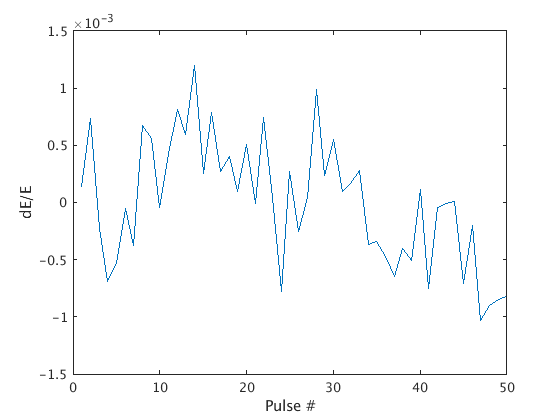

x=Ux*S*Vtx';
dp = x(:,BPMS.modelnames=="M1E") / disp ; % dP/P per pulse at energy BPM
figure
plot(dp); xlabel('Pulse #'); ylabel('dE/E');